# Assignment 5 

# Tracking of a moving object which trajectory is disturbed by random acceleration

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

**1)** Generateing a true trajectory$X_i$  of an object motion disturbed by normally distributed random acceleration. and mesurment $Z_i \;$for the trajectory 


$$\begin{array}{l}
X_i =X_{i-1} +V_{i-1} T+a_{i-1} \frac{T^2 }{2}\\
V_i =V_{i-1} +a_{i-1} T\\
Z_i =X_i +\eta 
\end{array}$$


Size of trajectory is 300 points.

Initial conditions: $X_1 =5;\;V_1 =0;\;T=0\ldotp 1;$

Variance of noise $a_{i\;} :\sigma_a^2 =0\ldotp 2^2$

Variance of noise $Z_{i\;} :\sigma_{\eta \;}^2 ={20}^2$

clc; clear; close all
T=1; N =200; x=1:200; x(1)=5; v=1:200; v(1)=1; Z=1:200; Z(1)=5+normrnd(0,20); Sigma_a=0.2^2;%vaiance of the acceleration a  
a=normrnd(0,sqrt(Sigma_a),1,200); % random acceleration. 
for i=2:N
    x(i)=x(i-1)+v(i-1)*T+(a(i-1)*T^2)/2; % position 
    v(i)=v(i-1)+a(i-1)*T;                % Velocity
    Z(i)=x(i)+normrnd(0,20);             % Measurments 
end 

**2) **Present the system at state space taking into account that only measurements of coordinate $X_i$are available.


$$\begin{array}{l}
X_i =\Phi X_{i-1} +{\mathrm{Ga}}_{i-1} \\
Z_i =H_i X_i +\eta_i 
\end{array}$$


phi=[1 T; 0 1]; 
G=[(T^2)/2; T]; 
H=[1 0] ; 
X_init=[2;0];                     % intial value of the state vector X=[x; v]. 

p_init=[10000 0;0 10000];         % intial value for p matrix. 
Q=G*G'*Sigma_a;                   % intial value for covariance Q. 
R=20^2;                           % intial value for covariance R.
K_init=p_init*H'/(H*p_init*H'+R); % initial value for the Kalman gain. 
filtered=ones(2,N);               % Matrix for holding the Kalman filter results. 
K=ones(2,N);                      % Matrix for hilding the galman gain. 
Err_p=1:N;                        % Aray for holding the error standardd deviation.
Err_t=1:N;                        % Aray for holding the True error.
m=7;                              % number of extrapolation steps. 
extrapolation=ones(2,N);          % Extrapolation results. 
 for i=1:N
   X_pre=phi*X_init;                  % prdection of X 
   p_pre=phi*p_init*phi'+Q;           % predection of P
   X_imp=X_pre+K_init*(Z(i)-H*X_pre); % Improving X with measurments. 
   X_ext_m=(phi^m)*X_imp;             % Extrapolation for m steps. 
   extrapolation(:,i)=X_ext_m;        
   K(:,i)=K_init;
   K_init=p_pre*H'/(H*p_pre*H'+R);    % Improving & updating the kalman gain. 
   filtered(:,i)=X_imp; 
   p_imp=(eye(2)-K_init*H)*p_pre;     % Improving P 
   Err_p(i)=sqrt(p_imp(1,1));
   p_init=p_imp;                      % updating P
   X_init=X_imp;                      % updating X
 end 

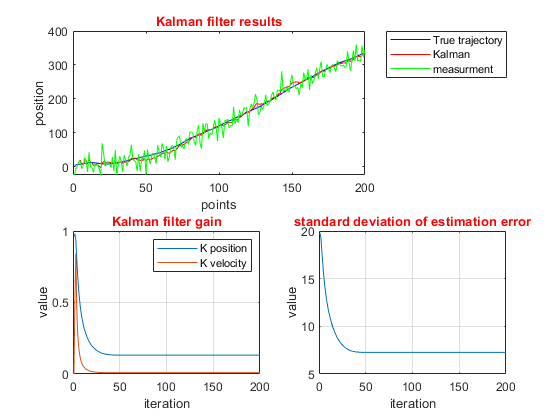

figure()                              % plotting results. 
subplot(2,2,[1,2])
plot(1:200,x,'b',1:200,filtered(1,:),'r',1:200,Z,'g')
title('Kalman filter results','color','r')
xlabel('points')
ylabel('position')
legend('True trajectory','Kalman','measurment','location','northeastoutside')
subplot(2,2,3)
plot(1:200,K(1,:),1:200,K(2,:))
title('Kalman filter gain','color','r')
xlabel('iteration')
ylabel('value')
legend('K position','K velocity')
grid on
subplot(2,2,4)
plot(1:200,Err_p);
title('standard deviation of estimation error','color','r')
xlabel('iteration')
ylabel('value')
grid on

**Comments:** 

1- In the first graph are the true trajectory, the measurements and the Kalman filter estimation graphed against each other, it can be seen that the estimation values are kind of following the trajectory with some disturbances. And plotting the filter with different random trajectories leads to the same results.

2- Plotting the Kalman filter gain for the X vector, it can be seen that the filter gain for the velocity approaches zero faster than the position gain and that’s because our measurements account only for the position, which leads to the observation matrix equal to H=[1 0] thus affects the value of the filtration gain for velocity. However, the filter gain related to the position of the trajectory approaches a constant value relatively fast.

3- Plotting the standard deviation resulting from the error covariance matrix, it also settles and reaches a constant value almost at the same rate of the filter gain.

Overall, both the standard deviation and filter gain settled for a constant value at a fast rate, thus verifying that given our conditions we cannot estimate more than the established limit of accuracy due to uncertainty.

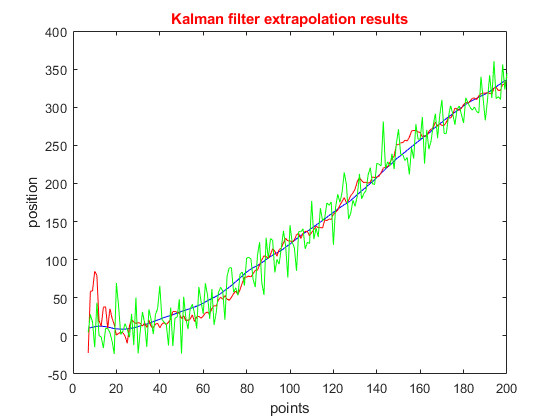

figure()
plot(m:200,x(m:200),'b',m:200, extrapolation(1,1:N-m+1),'r',m:200,Z(m:200),'g')
title('Kalman filter extrapolation results','color','r')
xlabel('points')
ylabel('position')

The plot above shows the extrapolation of 7 steps ahead against the true trajectory and the estimated filter, and a few observations can be noted, firstly, the extrapolation follows the behavior of the estimation more, which makes sense as it’s based on it, secondly, it’s more noisy at the beginning of the trajectory so it cannot be trusted at this region as an estimation of the true model, and lastly we can predict that both the error of filter estimation and the extrapolation will have the same behavior with close values.

**3)** Make M=500 runs of filter and estimate dynamics of mean-squared error of estimation over observation interval.calculate this error for filtered estimate of coordinate $X_{i,i}$and its forecasting (extrapolation).$X_{i,i+m-1}$.

clc; clear; 
Err_P=ones(500,200);
Err_F=ones(500,200);
Err_Ext=ones(500,194);
final_error=ones(1,198);
final_error_extrapolation=ones(1,194);
final_error_p=ones(1,198);
for M=1:500
    T=1; N =200; x=1:200; x(1)=5; v=1:200; v(1)=1; Z=1:200; Z(1)=5+normrnd(0,20); Sigma_a=0.2^2; %vaiance of the acceleration a  
    a=normrnd(0,sqrt(Sigma_a),1,200);        % random acceleration. 
    for i=2:N
        x(i)=x(i-1)+v(i-1)*T+(a(i-1)*T^2)/2; % position 
        v(i)=v(i-1)+a(i-1)*T;                % Velocity
        Z(i)=x(i)+normrnd(0,20);             % Measurments 
    end 
    phi=[1 T; 0 1]; 
    G=[(T^2)/2; T]; 
    H=[1 0] ; 
    X_init=[2;0];                     % intial value of the state vector X=[x; v].
    p_init=[10000 0;0 10000];         % intial value for p matrix. 
    Q=G*G'*Sigma_a;                   % intial value for covariance Q. 
    R=20^2;                           % intial value for covariance R.
    K_init=p_init*H'/(H*p_init*H'+R); % initial value for the Kalman gain. 
    filtered=ones(1,N);               % Matrix for holding the Kalman filter results. 
    K=ones(2,N);                      % Matrix for hilding the galman gain. 
    Err_p=1:N;                        % Aray for holding the error standardd deviation. 
    m=7;                              % number of extrapolation steps. 
    extrapolation=ones(1,N);          % Extrapolation results. 
    Err_f=ones(1,N);                  % estimation error
    Err_ext=ones(1,N-m+1);            % extrapolation with m steps error 
    for i=1:N
       X_pre=phi*X_init;                  % prdection of X 
       p_pre=phi*p_init*phi'+Q;           % predection of P
       X_imp=X_pre+K_init*(Z(i)-H*X_pre); % Improving X with measurments. 
       X_ext_m=(phi^m)*X_imp;             % Extrapolation for m steps. 
       extrapolation(i)=X_ext_m(1,1);     % Extrapolation saving
       K(:,i)=K_init;                     % kalman Gain array 
       K_init=p_pre*H'/(H*p_pre*H'+R);    % Improving & updating the kalman gain. 
       filtered(i)=X_imp(1,1);            % trajectory saving 
       p_imp=(eye(2)-K_init*H)*p_pre;     % Improving P 
       Err_p(i)=sqrt(p_imp(1,1));         % standard deviation of error 
       Err_f(i)=(x(i)-X_imp(1,1))^2;      % estimation error 
       p_init=p_imp;                      % updating P
       X_init=X_imp;                      % updating X
    end
    for i=1:N-m+1
        Err_ext(i)=(x(i+m-1)-extrapolation(i))^2;
    end
    Err_P(M,:)=Err_p;
    Err_F(M,:)=Err_f;
    Err_Ext(M,:)=Err_ext;
end
for i =1:N-2
    final_error(i)=sqrt((1/499)*sum(Err_F(:,i+2)));
    final_error_p(i)=(1/499)*sum(Err_P(:,i+2));
end
for i =1:N-m+1
   final_error_extrapolation(i)=sqrt((1/499)*sum(Err_Ext(:,i)));
end

figure()
subplot(2,1,1)
plot(1:198,final_error,1:198,final_error_p);
title('true vs standard deviation of estimation error','color','r');
xlabel('trajectory points');
ylabel('Value');
legend('True Error','calculated error from p matrix');
grid on

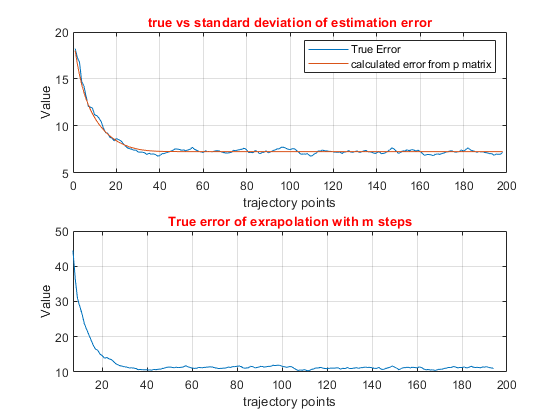

subplot(2,1,2)
plot(1:194,final_error_extrapolation);
xlim([7,200]);
title('True error of exrapolation with m steps','color','r');
xlabel('trajectory points');
ylabel('Value');
grid on 

Potting the averaged filter error and the standard deviation for $X_{i,i\;}$ they both have the same behavior with the filter error having fluctuations all over the observation period. Starting almost from the 40th time step we can see that the error settles to a certain range and that’s when the estimation accuracy doesn’t increase anymore, and it corresponds to the constant gain value as discussed in the assignment file. And the same behavior can be observed in the error from the extrapolation of 7-steps ahead, but a little bit shifted after the 40th iteration, and it had the same behavior of the filter error with its value, as expected in the previous point, was close to the value of the filter error, when filter error was equal to almost 7 it was equal to 10.

Comparing mean-squared error of filtered estimate of coordinate$X_{i,i}$ with standard deviation of measurement errors, they both approached a steady state behavior at the same time with the values of mean-squared error within the range of the constant value of the standard deviation. And this shows how we can depend on both of them interchangeably to predict the accuracy of our filter. And their values equal to almost 7 reflects a good estimation efficiency and effectiveness in filtering the noise.

**4) **make 500 runswith more accurate initial filtration error covariance matrix:


$$P_{0,0} =\left\lbrack \begin{array}{cc}
100 & 0\\
0 & 100
\end{array}\right\rbrack$$


clc; 
clear;
Err_P=ones(500,200);
Err_F=ones(500,200);
Err_Ext=ones(500,194);
final_error=ones(1,198);
final_error_extrapolation=ones(1,194);
final_error_p=ones(1,198);
for M=1:500
    T=1; N =200; x=1:200; x(1)=5; v=1:200; v(1)=1; Z=1:200; Z(1)=5+normrnd(0,20); Sigma_a=0.2^2; %vaiance of the acceleration a  
    a=normrnd(0,sqrt(Sigma_a),1,200);        % random acceleration. 
    for i=2:N
        x(i)=x(i-1)+v(i-1)*T+(a(i-1)*T^2)/2; % position 
        v(i)=v(i-1)+a(i-1)*T;                % Velocity
        Z(i)=x(i)+normrnd(0,20);             % Measurments 
    end 
    phi=[1 T; 0 1]; 
    G=[(T^2)/2; T]; 
    H=[1 0] ; 
    X_init=[2;0];                     % intial value of the state vector X=[x; v].
    p_init=[100 0;0 100];             % intial value for p matrix. 
    Q=G*G'*Sigma_a;                   % intial value for covariance Q. 
    R=20^2;                           % intial value for covariance R.
    K_init=p_init*H'/(H*p_init*H'+R); % initial value for the Kalman gain. 
    filtered=ones(1,N);               % Matrix for holding the Kalman filter results. 
    K=ones(2,N);                      % Matrix for hilding the galman gain. 
    Err_p=1:N;                        % Aray for holding the error standardd deviation. 
    m=7;                              % number of extrapolation steps. 
    extrapolation=ones(1,N);          % Extrapolation results. 
    Err_f=ones(1,N);                  % estimation error
    Err_ext=ones(1,N-m+1);            % extrapolation with m steps error 
    for i=1:N
       X_pre=phi*X_init;                  % prdection of X 
       p_pre=phi*p_init*phi'+Q;           % predection of P
       X_imp=X_pre+K_init*(Z(i)-H*X_pre); % Improving X with measurments. 
       X_ext_m=(phi^m)*X_imp;             % Extrapolation for m steps. 
       extrapolation(i)=X_ext_m(1,1);     % Extrapolation saving
       K(:,i)=K_init;                     % kalman Gain array 
       K_init=p_pre*H'/(H*p_pre*H'+R);    % Improving & updating the kalman gain. 
       filtered(i)=X_imp(1,1);            % trajectory saving 
       p_imp=(eye(2)-K_init*H)*p_pre;     % Improving P 
       Err_p(i)=sqrt(p_imp(1,1));         % standard deviation of error 
       Err_f(i)=(x(i)-X_imp(1,1))^2;      % estimation error 
       p_init=p_imp;                      % updating P
       X_init=X_imp;                      % updating X
    end
    for i=1:N-m+1
        Err_ext(i)=(x(i+m-1)-extrapolation(i))^2;
    end
    Err_P(M,:)=Err_p;
    Err_F(M,:)=Err_f;
    Err_Ext(M,:)=Err_ext;
end
for i =1:N-2
    final_error(i)=sqrt((1/499)*sum(Err_F(:,i+2)));
    final_error_p(i)=(1/499)*sum(Err_P(:,i+2));
end
for i =1:N-m+1
   final_error_extrapolation(i)=sqrt((1/499)*sum(Err_Ext(:,i)));
end

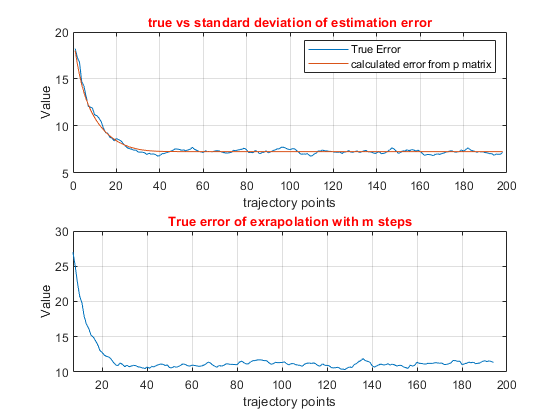

plot(1:198,final_error,1:198,final_error_p);
title('true vs standard deviation of estimation error','color','r');
xlabel('trajectory points');
ylabel('Value');
legend('True Error','calculated error from p matrix');
grid on
plot(1:194,final_error_extrapolation);
xlim([7,200]);
title('True error of exrapolation with m steps','color','r');
xlabel('trajectory points');
ylabel('Value');
grid on

Comparing the results obtained with P10000=[10000 0;0 10000] and P100=[100 0;0 100], it can be noticed that they both eventually settle on the same steady-state error value which is almost 7 for both, also the rate they reached that value was close but in the case of P100 it was faster, what was a big difference though is the value of the error before it settled. The value of the error was less when using the P100, and this can be interpreted as the initial value of covariance matrix here was close to the optimal matrix to use at the initial points. And we can conclude that changing the initial value of the covariance matrix affects the values filtered at the starting of the running filtration but as long as our model is correct any value would settle with the same effectiveness and if the guess is the more close to the optimal value the rate will be faster. And the same conclusion applies to the error of 7-steps ahead extrapolation.

Comparing calculation errors of estimation P and the Kalman filter true estimation error, we can see that P corresponds to that error in behavior and values when using the P1000 but when using the P100 the values were a bit higher for the P matrix at the beginning but the both settled on almost the same constant value with the same rate, so we can depend on both of them to be interchangeable and that the calculation errors of estimation correspond to true estimation errors.

**5) **Run filter for deterministic trajectory (no random disturbance). It can be easily done by indicating in the code that variance of state noise equals to zero $\sigma_a^2 =0$. make 500 runs to verfiy that fiter gain and calculation errors approches zero. 

clc; 
clear;
Err_P=ones(500,200);
Err_F=ones(500,200);
Err_Ext=ones(500,194);
final_error=ones(1,198);
final_error_extrapolation=ones(1,194);
final_error_p=ones(1,198);
for M=1:500
    T=1; N =200; x=1:200; x(1)=5; v=1:200; v(1)=1; Z=1:200; Z(1)=5+normrnd(0,20); Sigma_a=0; %vaiance of the acceleration a  
    a=normrnd(0,sqrt(Sigma_a),1,200);        % random acceleration. 
    for i=2:N
        x(i)=x(i-1)+v(i-1)*T+(a(i-1)*T^2)/2; % position 
        v(i)=v(i-1)+a(i-1)*T;                % Velocity
        Z(i)=x(i)+normrnd(0,20);             % Measurments 
    end 
    phi=[1 T; 0 1]; 
    G=[(T^2)/2; T]; 
    H=[1 0] ; 
    X_init=[2;0];                     % intial value of the state vector X=[x; v].
    p_init=[10000 0;0 10000];         % intial value for p matrix. 
    Q=G*G'*Sigma_a;                   % intial value for covariance Q. 
    R=20^2;                           % intial value for covariance R.
    K_init=p_init*H'/(H*p_init*H'+R); % initial value for the Kalman gain. 
    filtered=ones(1,N);               % Matrix for holding the Kalman filter results. 
    K=ones(2,N);                      % Matrix for hilding the galman gain. 
    Err_p=1:N;                        % Aray for holding the error standardd deviation. 
    m=7;                              % number of extrapolation steps. 
    extrapolation=ones(1,N);          % Extrapolation results. 
    Err_f=ones(1,N);                  % estimation error
    Err_ext=ones(1,N-m+1);            % extrapolation with m steps error 
    for i=1:N
       X_pre=phi*X_init;                  % prdection of X 
       p_pre=phi*p_init*phi'+Q;           % predection of P
       X_imp=X_pre+K_init*(Z(i)-H*X_pre); % Improving X with measurments. 
       X_ext_m=(phi^m)*X_imp;             % Extrapolation for m steps. 
       extrapolation(i)=X_ext_m(1,1);     % Extrapolation saving
       K(:,i)=K_init;                     % kalman Gain array 
       K_init=p_pre*H'/(H*p_pre*H'+R);    % Improving & updating the kalman gain. 
       filtered(i)=X_imp(1,1);            % trajectory saving 
       p_imp=(eye(2)-K_init*H)*p_pre;     % Improving P 
       Err_p(i)=sqrt(p_imp(1,1));         % standard deviation of error 
       Err_f(i)=(x(i)-X_imp(1,1))^2;      % estimation error 
       p_init=p_imp;                      % updating P
       X_init=X_imp;                      % updating X
    end
    for i=1:N-m+1
        Err_ext(i)=(x(i+m-1)-extrapolation(i))^2;
    end
    Err_P(M,:)=Err_p;
    Err_F(M,:)=Err_f;
    Err_Ext(M,:)=Err_ext;
end
for i =1:N-2
    final_error(i)=sqrt((1/499)*sum(Err_F(:,i+2)));
    final_error_p(i)=(1/499)*sum(Err_P(:,i+2));
end
for i =1:N-m+1
   final_error_extrapolation(i)=sqrt((1/499)*sum(Err_Ext(:,i)));
end

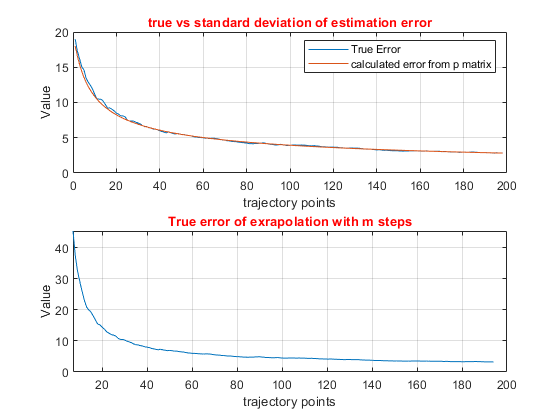

figure()
subplot(2,1,1)
plot(1:198,final_error,1:198,final_error_p);
title('true vs standard deviation of estimation error','color','r');
xlabel('trajectory points');
ylabel('Value');
legend('True Error','calculated error from p matrix');
grid on
subplot(2,1,2)
plot(1:194,final_error_extrapolation);
xlim([7,200]);
title('True error of exrapolation with m steps','color','r');
xlabel('trajectory points');
ylabel('Value');
grid on

Using the deterministic model with sigma_a=0, a significant change in the result happened  compared to the noisy model, as the values went faster and more accurately to the real trajectory, certainly due to non-existing acceleration noise. And verifying for the gain value and the error we reached that:

1-	The filter gain K as seen in the plot approach zero and if we run it for more time steps we shall expect to reach zero eventually.

2-	The true estimation errors and calculation errors $p_{i,i}$ they both approach zero in a fast rate.

Which verifies that in conditions of motion without any random disturbances, the filter switches off from measurements and that new measurements don’t affect our estimation.

**6)  **Verify what happens if you use deterministic model of motion, but in fact motion is disturbed by random acceleration:

clc; 
clear;
Err_P=ones(500,200);
Err_F=ones(500,200);
Err_Ext=ones(500,194);
final_error=ones(1,198);
final_error_extrapolation=ones(1,194);
final_error_p=ones(1,198);
for M=1:500
    T=1; N =200; x=1:200; x(1)=5; v=1:200; v(1)=1; Z=1:200; Z(1)=5+normrnd(0,20); Sigma_a=0.2^2;%vaiance of the acceleration a  
    a=normrnd(0,sqrt(Sigma_a),1,200);        % random acceleration. 
    for i=2:N
        x(i)=x(i-1)+v(i-1)*T+(a(i-1)*T^2)/2; % position 
        v(i)=v(i-1)+a(i-1)*T;                % Velocity
        Z(i)=x(i)+normrnd(0,20);             % Measurments 
    end 
    phi=[1 T; 0 1]; 
    G=[(T^2)/2; T]; 
    H=[1 0] ; 
    X_init=[2;0];                     % intial value of the state vector X=[x; v].
    p_init=[10000 0;0 10000];         % intial value for p matrix. 
    Q=0;                              % intial value for covariance Q. 
    R=20^2;                           % intial value for covariance R.
    K_init=p_init*H'/(H*p_init*H'+R); % initial value for the Kalman gain. 
    filtered=ones(1,N);               % Matrix for holding the Kalman filter results. 
    K=ones(2,N);                      % Matrix for hilding the galman gain. 
    Err_p=1:N;                        % Aray for holding the error standardd deviation. 
    m=7;                              % number of extrapolation steps. 
    extrapolation=ones(1,N);          % Extrapolation results. 
    Err_f=ones(1,N);                  % estimation error
    Err_ext=ones(1,N-m+1);            % extrapolation with m steps error 
    for i=1:N
       X_pre=phi*X_init;                  % prdection of X 
       p_pre=phi*p_init*phi'+Q;           % predection of P
       X_imp=X_pre+K_init*(Z(i)-H*X_pre); % Improving X with measurments. 
       X_ext_m=(phi^m)*X_imp;             % Extrapolation for m steps. 
       extrapolation(i)=X_ext_m(1,1);     % Extrapolation saving
       K(:,i)=K_init;                     % kalman Gain array 
       K_init=p_pre*H'/(H*p_pre*H'+R);    % Improving & updating the kalman gain. 
       filtered(i)=X_imp(1,1);            % trajectory saving 
       p_imp=(eye(2)-K_init*H)*p_pre;     % Improving P 
       Err_p(i)=sqrt(p_imp(1,1));         % standard deviation of error 
       Err_f(i)=(x(i)-X_imp(1,1))^2;      % estimation error 
       p_init=p_imp;                      % updating P
       X_init=X_imp;                      % updating X
    end
    for i=1:N-m+1
        Err_ext(i)=(x(i+m-1)-extrapolation(i))^2;
    end
    Err_P(M,:)=Err_p;
    Err_F(M,:)=Err_f;
    Err_Ext(M,:)=Err_ext;
end
for i =1:N-2
    final_error(i)=sqrt((1/499)*sum(Err_F(:,i+2)));
    final_error_p(i)=(1/499)*sum(Err_P(:,i+2));
end
for i =1:N-m+1
   final_error_extrapolation(i)=sqrt((1/499)*sum(Err_Ext(:,i)));
end

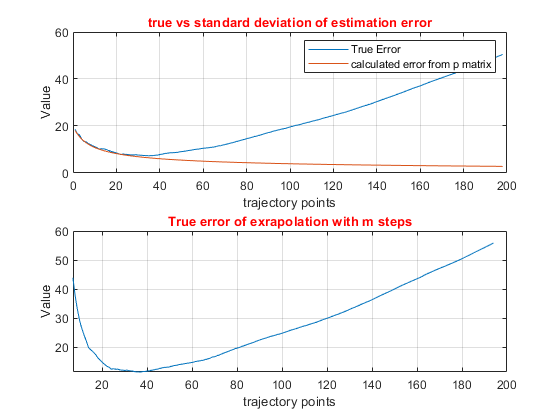

figure()
subplot(2,1,1)
plot(1:198,final_error,1:198,final_error_p);
title('true vs standard deviation of estimation error','color','r');
xlabel('trajectory points');
ylabel('Value');
legend('True Error','calculated error from p matrix');
grid on
subplot(2,1,2)
plot(1:194,final_error_extrapolation);
xlim([7,200]);
title('True error of exrapolation with m steps','color','r');
xlabel('trajectory points');
ylabel('Value');
grid on

Using the deterministic model without accounting for the noise although it exist, we can see that our model behave differently as the result diverged significantly from the true trajectory, both the true estimation error and calculation error didn’t match in values and the 7-steps ahead extrapolation was accordingly diverged.

1.	Comparing the results obtained at item 1 through 9 with results in the current conditions, it can be observed that the true estimation error settled for optimal calculation conditions while what we did in here resulted in a non-stopping increase in that error. Which is also applicable when we talk about the 7-steps ahead extrapolation’s true estimation error.

2.	 While the calculation error settled for both cases and approached a small value, which isn’t true in this case. Which means we cannot rely on this error for this particular case.

**7)  **Analyze how the relationship between state and measurement noise affects time when filter gain become almost constant and estimation accuracy doesn’t increase anymore: 

clc; 
clear;
Err_P=ones(500,200);
Err_F=ones(500,200);
Err_Ext=ones(500,194);
final_error=ones(1,198);
final_error_extrapolation=ones(1,194);
final_error_p=ones(1,198);
for M=1:500
    T=1; N =200; x=1:200; x(1)=5; v=1:200; v(1)=1; Z=1:200; Z(1)=5+normrnd(0,20); Sigma_a=1;%vaiance of the acceleration a  
    a=normrnd(0,sqrt(Sigma_a),1,200);        % random acceleration. 
    for i=2:N
        x(i)=x(i-1)+v(i-1)*T+(a(i-1)*T^2)/2; % position 
        v(i)=v(i-1)+a(i-1)*T;                % Velocity
        Z(i)=x(i)+normrnd(0,20);             % Measurments 
    end 
    phi=[1 T; 0 1]; 
    G=[(T^2)/2; T]; 
    H=[1 0] ; 
    X_init=[2;0];                     % intial value of the state vector X=[x; v].
    p_init=[10000 0;0 10000];         % intial value for p matrix. 
    Q=G*G'*Sigma_a;                   % intial value for covariance Q. 
    R=20^2;                           % intial value for covariance R.
    K_init=p_init*H'/(H*p_init*H'+R); % initial value for the Kalman gain. 
    filtered=ones(1,N);               % Matrix for holding the Kalman filter results. 
    K=ones(2,N);                      % Matrix for hilding the galman gain. 
    Err_p=1:N;                        % Aray for holding the error standardd deviation. 
    m=7;                              % number of extrapolation steps. 
    extrapolation=ones(1,N);          % Extrapolation results. 
    Err_f=ones(1,N);                  % estimation error
    Err_ext=ones(1,N-m+1);            % extrapolation with m steps error 
    for i=1:N
       X_pre=phi*X_init;                  % prdection of X 
       p_pre=phi*p_init*phi'+Q;           % predection of P
       X_imp=X_pre+K_init*(Z(i)-H*X_pre); % Improving X with measurments. 
       X_ext_m=(phi^m)*X_imp;             % Extrapolation for m steps. 
       extrapolation(i)=X_ext_m(1,1);     % Extrapolation saving
       K(:,i)=K_init;                     % kalman Gain array 
       K_init=p_pre*H'/(H*p_pre*H'+R);    % Improving & updating the kalman gain. 
       filtered(i)=X_imp(1,1);            % trajectory saving 
       p_imp=(eye(2)-K_init*H)*p_pre;     % Improving P 
       Err_p(i)=sqrt(p_imp(1,1));         % standard deviation of error 
       Err_f(i)=(x(i)-X_imp(1,1))^2;      % estimation error 
       p_init=p_imp;                      % updating P
       X_init=X_imp;                      % updating X
    end
    for i=1:N-m+1
        Err_ext(i)=(x(i+m-1)-extrapolation(i))^2;
    end
    Err_P(M,:)=Err_p;
    Err_F(M,:)=Err_f;
    Err_Ext(M,:)=Err_ext;
end
for i =1:N-2
    final_error(i)=sqrt((1/499)*sum(Err_F(:,i+2)));
    final_error_p(i)=(1/499)*sum(Err_P(:,i+2));
end
for i =1:N-m+1
   final_error_extrapolation(i)=sqrt((1/499)*sum(Err_Ext(:,i)));
end

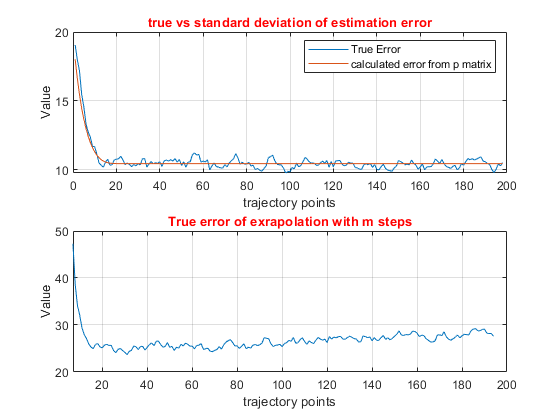

figure()
subplot(2,1,1)
plot(1:198,final_error,1:198,final_error_p);
title('true vs standard deviation of estimation error','color','r');
xlabel('trajectory points');
ylabel('Value');
legend('True Error','calculated error from p matrix');
grid on
subplot(2,1,2)
plot(1:194,final_error_extrapolation);
xlim([7,200]);
title('True error of exrapolation with m steps','color','r');
xlabel('trajectory points');
ylabel('Value');
grid on

As the filter gain settled for a value and using the new value for sigma_a we can see that the accuracy of filtration decreased with higher value of sigma and it can be observed from the error, which has reached a constant value, but a higher value compared to the old sigma_a. which gives an obvious conclusion, that whenever the noise increase or the complexity of the dynamics of the system the more the filter is inclined to fail in filtering the data from the noise.

**8) **Analyze sensitivity of filter to underestimated non-optimal filter gain K.

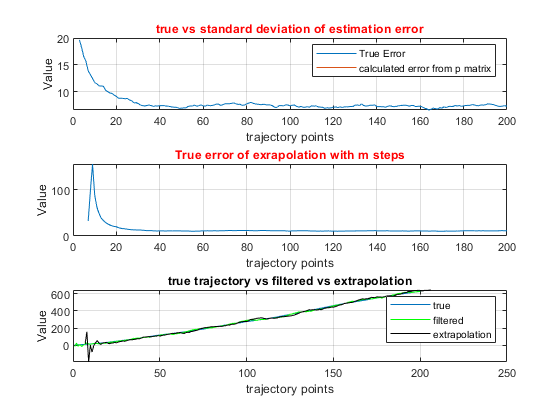

close all;
clear;
Err=zeros(500,200);
ErrE=zeros(500,194);
Ksteady=zeros(2,200);
for M=1:500
    normaldist=makedist('Normal',0,0.2);
    a=random(normaldist,200,1);
    X=zeros(1,200);
    X(1)=5;
    V=zeros(1,200);
    V(1)=1;
    T=1;
    N=length(X);
    for i=2:N
        X(i)=X(i-1)+V(i-1)*T+a(i-1)*T^2/2;
        V(i)=V(i-1)+a(i-1)*T;
    end

    normaldist2=makedist('Normal',0,20);
    eta=random(normaldist2,200,1);
    Z=zeros(1,200);
    N=length(X);
    for i=1:N
        Z(i)=X(i)+eta(i);
    end
    X1=X;

    phi=[1 T;0 1];
    G=[T^2; T];
    H=[1 0];

    xi=zeros(1,200);
    Xi=[100;5];
    P=[10000 0; 0 10000];

    R=20^2;
    sigma_a=0.2^2;
    K=P*H'/(H*P*H'+R);
    Ki=zeros(N,2);
    Pi=zeros(N,1);
    xiE=zeros(N,1);
    for i=1:2
        Xi=phi*Xi;
        Q=G*G'*sigma_a;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(2)-K*H)*P;
        Pi(i)=sqrt(P(1,1));
        XiE=Xi;
        for m=1:6
            XiE=phi*XiE;
            xx(:,m)=phi*XiE;
        end
        xiE(i)=XiE(1);
        ErrE(M,i)=(XiE(1)-X(i+6))^2;
    end
     for i=3:N
        K1=K;
        Xi=phi*Xi;
        Q=G*G'*sigma_a;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        K=P*H'/(H*P*H'+R);
        Ki(i,:)=K';
        P=(eye(2)-K*H)*P;
        Pi(i)=sqrt(P(1,1));
        Err(M,i)=(Xi(1)-X(i))^2;
        if abs(K-K1)/K<0.05
            Ksteady(:,M)=K;
        end
        XiE=Xi;
        for m=1:6
            XiE=phi*XiE;
        end
        xiE(i)=XiE(1);
        if i<N-5
            ErrE(M,i)=(XiE(1)-X(i+6))^2;
        end
    end
end
ErrAvg=zeros(1,N-2);
for j=1:N-2;
    ErrAvg(j)=sqrt((1/(M-1))*sum(Err(:,j+2)));
end
ErrAvgE=zeros(1,N-6);
for j=1:N-6;
    ErrAvgE(j)=sqrt((1/(M-1))*sum(ErrE(:,j)));
end
figure()
subplot(3,1,1)
plot(3:N,ErrAvg,3:N,Pi(3,:))
title('true vs standard deviation of estimation error','color','r');
xlabel('trajectory points');
ylabel('Value');
legend('True Error','calculated error from p matrix');
grid on
subplot(3,1,2)
plot(7:N,ErrAvgE)
title('True error of exrapolation with m steps','color','r');
xlabel('trajectory points');
ylabel('Value');
grid on
subplot(3,1,3)
plot(X)
hold on
plot(xi,'g')
plot(7:N+6,xiE,'k')
title('true trajectory vs filtered vs extrapolation')
legend('true','filtered','extrapolation')
xlabel('trajectory points');
ylabel('Value');
grid on

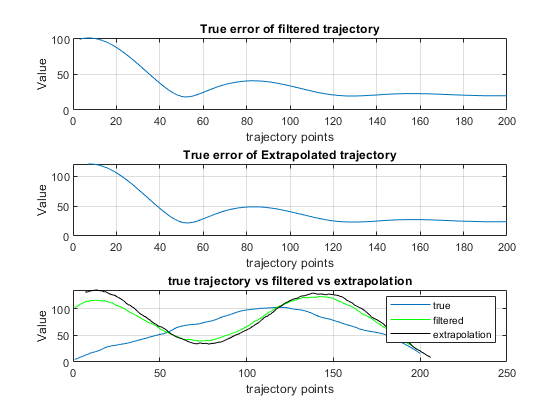

Ks(1,1)=mean(Ksteady(1,:));
Ks(2,1)=mean(Ksteady(2,:));
ErrS=zeros(500,200);
ErrES=zeros(500,194);
for M=1:500
    normaldist=makedist('Normal',0,0.2);
    a=random(normaldist,200,1);
    X=zeros(1,200);
    X(1)=5;
    V=zeros(1,200);
    V(1)=1;
    T=1;
    N=length(X);
    for i=2:N
        X(i)=X(i-1)+V(i-1)*T+a(i-1)*T^2/2;
        V(i)=V(i-1)++a(i-1)*T;
    end

    normaldist2=makedist('Normal',0,20);
    eta=random(normaldist2,200,1);
    Z=zeros(1,200);
    N=length(X);
    for i=1:N
        Z(i)=X(i)+eta(i);
    end
    X1=X;

    phi=[1 T;0 1];
    G=[T^2; T];
    H=[1 0];

    xi=zeros(1,200);
    Xi=[100;5];
    P=[10000 0; 0 10000];

    R=20^2;
    sigma_a=0.2^2;
    K=Ks/5;
    PiS=zeros(N,1);
    xiES=zeros(N,1);
    for i=1:2
        Xi=phi*Xi;
        Q=G*G'*sigma_a;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        P=(eye(2)-K*H)*P;
        PiS(i)=sqrt(abs(P(1,1)));
        XiE=Xi;
        for m=1:6
            XiE=phi*XiE;
        end
        xiES(i)=XiE(1);
        ErrES(M,i)=(XiE(1)-X(i+6))^2;
    end
     for i=3:N
        Xi=phi*Xi;
        Q=G*G'*sigma_a;
        P=phi*P*phi'+Q;
        Xi=Xi+K*(Z(i)-H*Xi);
        xi(i)=Xi(1);
        P=(eye(2)-K*H)*P;
        PiS(i)=sqrt(abs(P(1,1)));
        ErrS(M,i)=(Xi(1)-X(i))^2;
        XiE=Xi;
        for m=1:6
            XiE=phi*XiE;
        end
        xiES(i)=XiE(1);
        if i<N-5
            ErrES(M,i)=(XiE(1)-X(i+6))^2;
        end
    end
end
figure
ErrAvgS=zeros(1,N-2);
for j=1:N-2;
    ErrAvgS(j)=sqrt((1/(M-1))*sum(ErrS(:,j+2)));
end

ErrAvgES=zeros(1,N-6);
for j=1:N-6;
    ErrAvgES(j)=sqrt((1/(M-1))*sum(ErrES(:,j)));
end
figure()
subplot(3,1,1)
plot(3:N,ErrAvgS)
title('True error of filtered trajectory')
xlabel('trajectory points');
ylabel('Value');
grid on
subplot(3,1,2)
plot(7:N,ErrAvgES)
title('True error of Extrapolated trajectory')
xlabel('trajectory points');
ylabel('Value');
grid on
subplot(3,1,3)
plot(X)
hold on
plot(xi,'g')
hold on 
plot(7:N+6,xiES,'k')
title('true trajectory vs filtered vs extrapolation')
legend('true','filtered','extrapolation')
xlabel('trajectory points');
ylabel('Value');
grid on

Using the X=[100,5] and comparing the results with what we obtained earlier, we can see that the filtration also converged to the true trajectory when using optimal K. However, after we used the steady state gain, we can see a big difference and a huge deviation from the real model which gives us the sense of how choosing an initial estimation affects the end result in case of constant gain.

1-      Calculating the filter gain for this condition, it was similar to the value of the conditions we used at the beginning of the assignment with K=[0.139; 0.0093] for both and the filtered trajectory followed the same behaviour with the same steady state calculation error. Which shows us that the gain depends mainly on the statistical properties of the given system, even if we used a far value for the initial conditions, the end result would be the same.

# Learning Log:

This assignment by far was the most challenging one as it contained a lot of analysis to conduct and a lot of variation to include in our system. We have learned more about the Kalman filter, using different variations of both our system and the filter itself; which gave us a wholesome of the practical sense to conduct analysis with a Kalman filter. We have learned how sensitive data analysis is, and how the models we come up with are affected by our inputs as well as the measured data. And if we conclude some points and to reflect on our learning:

1- Kalman filter and probably other filtration methods are sensitive to the input parameters and we cannot get a good approximation of our true system unless we have an understanding of its physics.

2- Forecasting new data using optimal conditions for the Kalman filter is to a great extent effective but to a short range of time, as we tried to increase the prediction steps and the more forecasting steps you use the more the error increases and vice versa.

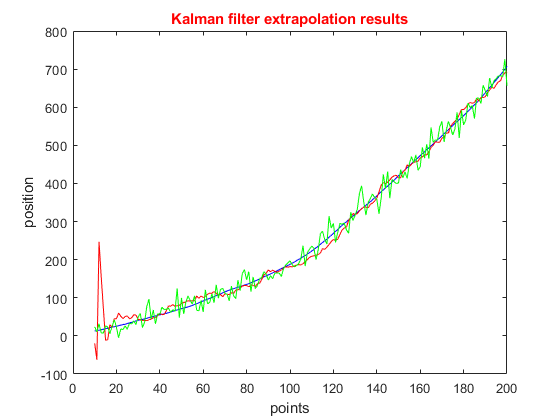

clc; clear; close all
T=1; N =200; x=1:200; x(1)=5; v=1:200; v(1)=1; Z=1:200; Z(1)=5+normrnd(0,20); Sigma_a=0.2^2;%vaiance of the acceleration a  
a=normrnd(0,sqrt(Sigma_a),1,200); % random acceleration. 
for i=2:N
    x(i)=x(i-1)+v(i-1)*T+(a(i-1)*T^2)/2; % position 
    v(i)=v(i-1)+a(i-1)*T;                % Velocity
    Z(i)=x(i)+normrnd(0,20);             % Measurments 
end 
phi=[1 T; 0 1]; 
G=[(T^2)/2; T]; 
H=[1 0] ; 
X_init=[2;0]; 
p_init=[10000 0;0 10000];         % intial value for p matrix. 
Q=G*G'*Sigma_a;                   % intial value for covariance Q. 
R=20^2;                           % intial value for covariance R.
K_init=p_init*H'/(H*p_init*H'+R); % initial value for the Kalman gain. 
filtered=ones(2,N);               % Matrix for holding the Kalman filter results. 
K=ones(2,N);                      % Matrix for hilding the galman gain. 
Err_p=1:N;                        % Aray for holding the error standardd deviation.
Err_t=1:N;                        % Aray for holding the True error.
m=10;                              % number of extrapolation steps. 
extrapolation=ones(2,N);          % Extrapolation results. 
 for i=1:N
   X_pre=phi*X_init;                  % prdection of X 
   p_pre=phi*p_init*phi'+Q;           % predection of P
   X_imp=X_pre+K_init*(Z(i)-H*X_pre); % Improving X with measurments. 
   X_ext_m=(phi^m)*X_imp;             % Extrapolation for m steps. 
   extrapolation(:,i)=X_ext_m;        
   K(:,i)=K_init;
   K_init=p_pre*H'/(H*p_pre*H'+R);    % Improving & updating the kalman gain. 
   filtered(:,i)=X_imp; 
   p_imp=(eye(2)-K_init*H)*p_pre;     % Improving P 
   Err_p(i)=sqrt(p_imp(1,1));
   p_init=p_imp;                      % updating P
   X_init=X_imp;                      % updating X
 end 
 figure()
plot(m:200,x(m:200),'b',m:200, extrapolation(1,1:N-m+1),'r',m:200,Z(m:200),'g')
title('Kalman filter extrapolation results','color','r')
xlabel('points')
ylabel('position')

3- The same Kalman filter gain can be used for systems with the same statistical properties and the end result will be almost the same. So we can calculate the gain one time and use it for the same experiment multiple times.

4- Using the steady state value for Kalman filter we used the first element of the measurements for a better initial conditions and we expected to obtain a different shape for the error graph, instead of the oscillatory behaviour we obtained earlier, but it turned out that it wasn’t that different and probably it’s kind of a systematic error because of the constant value of K, given our system.